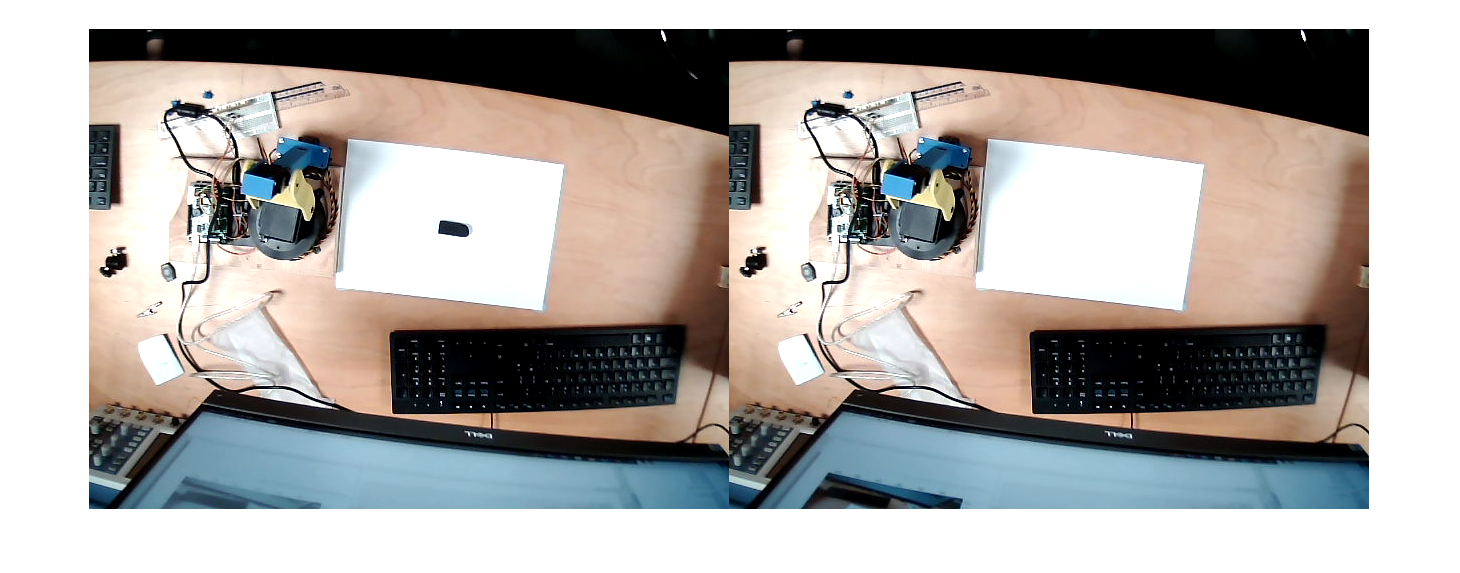

%%%%%%%%%%%%%%%%
% Import Image %
%%%%%%%%%%%%%%%%

I = imread('object1.png'); 
I2 = imread('NoObject.png'); 
CornerThreshold = 4;

%%%%%%%%%%%%%%%%%%%%
% Preprocess Image %
%%%%%%%%%%%%%%%%%%%%

%Transform into greyscale
IRed = double(I(:,:,1));          
IGreen = double(I(:,:,2));
IBlue = double(I(:,:,3));
IGrey = (IRed+IGreen+IBlue)/3;
IGrey = uint8(IGrey);

I2Red = double(I2(:,:,1));          
I2Green = double(I2(:,:,2));
I2Blue = double(I2(:,:,3));
I2Grey = (I2Red+I2Green+I2Blue)/3;
I2Grey = uint8(I2Grey);

%Histogram of image
figure , imshowpair(I,I2,'montage')

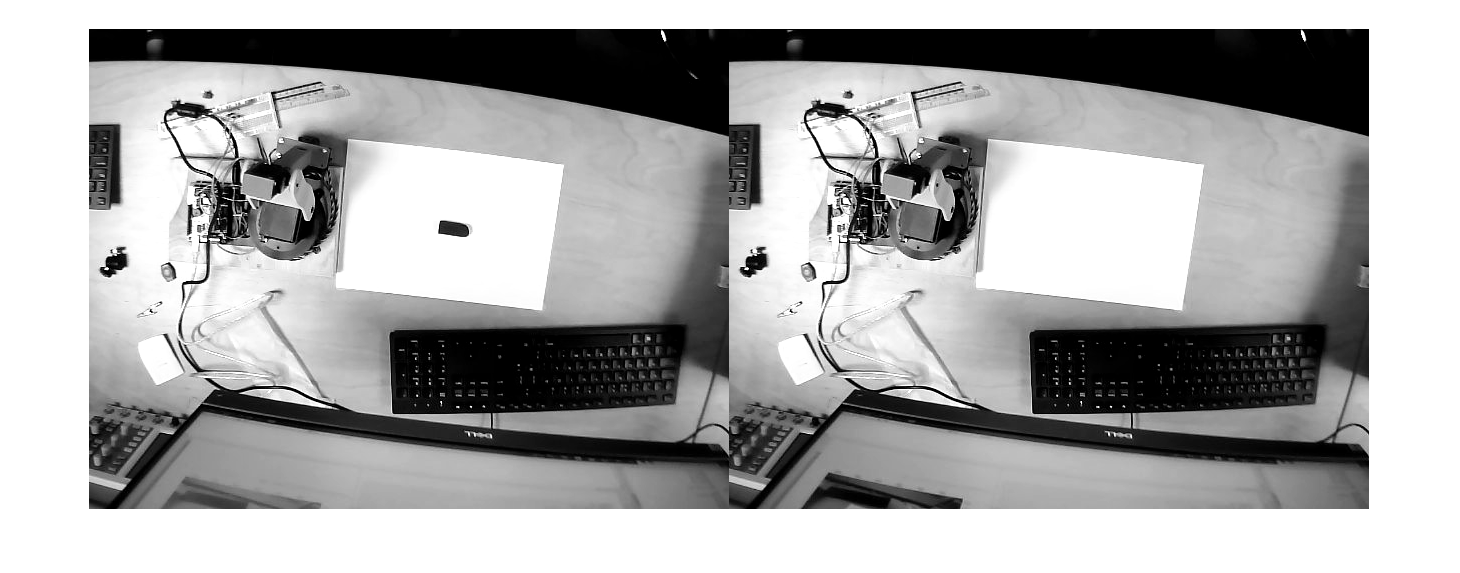

figure , imshowpair(IGrey,I2Grey,'montage')

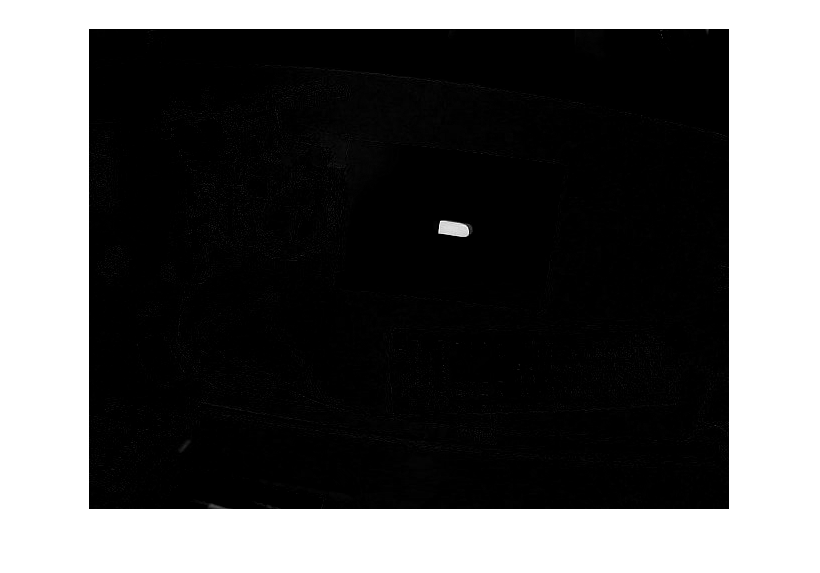

figure, imhist(IGrey)                   
title('Histogram')

IGrey = I2Grey - IGrey;
figure , imshow(IGrey)

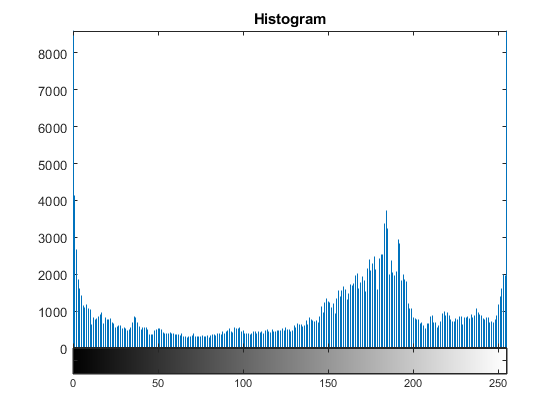


IGrey=double(IGrey);
[m,n]=size(IGrey);

%Thresholding
Ithreshold = zeros(m,n);

for i = 1:m
    for j = 1:n
        if IGrey(i,j) > 90              
            Ithreshold(i,j) = 255;
        else
            Ithreshold(i,j) = 0;
        end
    end
end

Ithreshold = uint8(Ithreshold);
[m,n]=size(Ithreshold);
figure,imshow(Ithreshold)

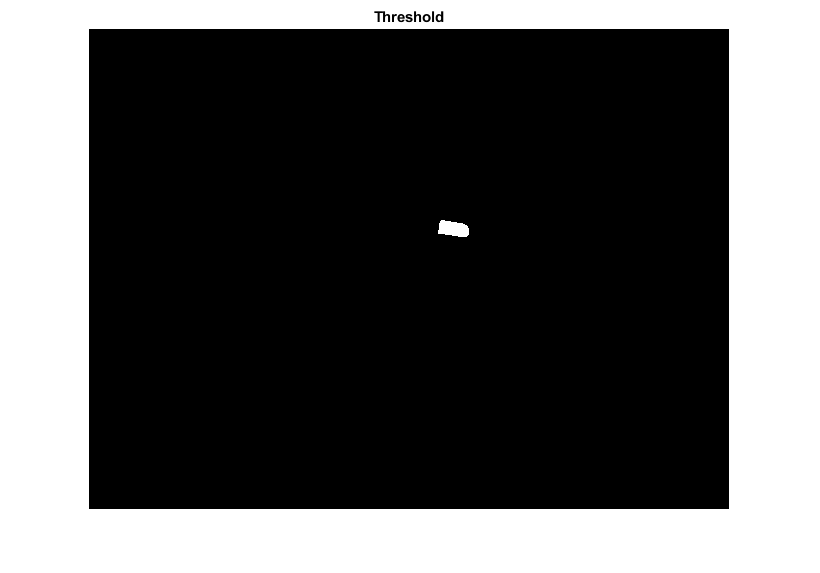

title('Threshold')

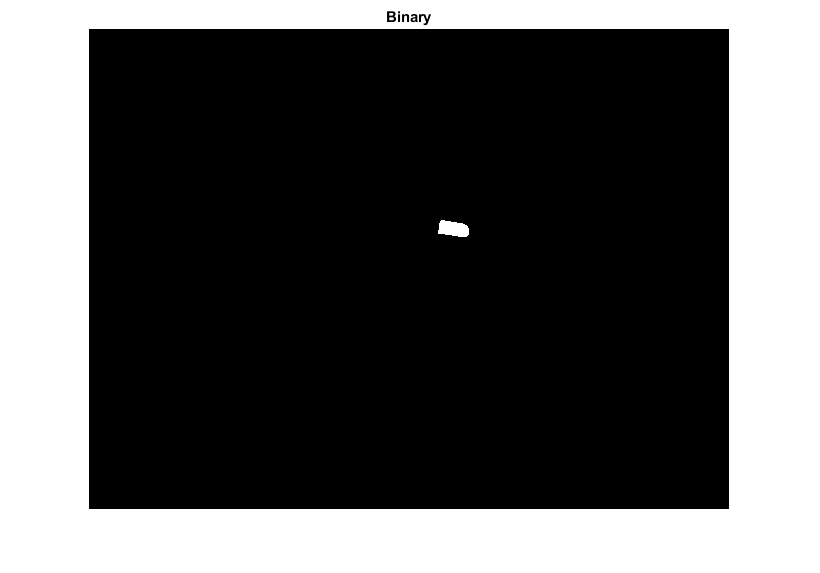


% Imedian = uint8(Imedian);
% Imedian=double(Imedian);
% figure,imshow(Imedian)
% title('Median Filtered')

%Binary image
Ibw = imbinarize(Ithreshold);
figure,imshow(Ibw);
title('Binary')


% %%%%%%%%%%%%%%%%%%%%%%%%%%
% Position and Orientation %
% %%%%%%%%%%%%%%%%%%%%%%%%%%

% position is centre of gravity of object

M = zeros(3,3);

for p = 1:3
    for q = 1:3
        for y = 1:m
            for x = 1:n
                M(p,q) = M(p,q) + x^(p-1) * y^(q-1) * Ibw(y,x);
            end
        end
    end
end

M

M = 	1.0e+12 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0059
    0.0001    0.0107    2.1492



Xc = M(2,1)/M(1,1)

Xc = 364.9277

Yc = M(1,2)/M(1,1)

Yc = 200.4638


mu = zeros(3,3);
mu(1,1) = M(1,1);
mu(2,2) = M(2,2) - Xc*M(1,2);
mu(3,1) = M(3,1) - Xc*M(2,1);
mu(1,3) = M(1,3) - Yc*M(1,2);
mu

mu = 	1.0e+04 *

    0.0401         0    0.6662
         0    0.3868         0
    2.8485         0         0



J = [mu(3,1) mu(2,2); mu(2,2) mu(1,3)]

J = 	1.0e+04 *

    2.8485    0.3868
    0.3868    0.6662



[V,D] = eig(J)

V =     0.1695   -0.9855
   -0.9855   -0.1695


D = 	1.0e+04 *

    0.5996         0
         0    2.9150



if D(1,1) > D(2,2)
    a = 2*sqrt(D(1,1)/M(1,1))
    b = 2*sqrt(D(2,2)/M(1,1))
    theta = atan2(V(2,1),V(1,1))
else
    a = 2*sqrt(D(2,2)/M(1,1))
    b = 2*sqrt(D(1,1)/M(1,1))
    V(2,2)
    V(1,2)
    theta = atan2(V(2,2),V(1,2))
end

a = 17.0522

b = 7.7339

ans = -0.1695

ans = -0.9855

theta = -2.9712


minoraxis = b

minoraxis = 7.7339

majoraxis = a

majoraxis = 17.0522

Orientation = theta*180/pi

Orientation = -170.2396

centroid = [Xc Yc]

centroid =   364.9277  200.4638



%Laplacian Edge

Iedgexy = zeros(m,n); 

for i = 2:m-1
    for j = 2:n-1
        Iedgexy(i,j) = (-1*Ibw(i-1,j-1)-1*Ibw(i-1,j)-1*Ibw(i-1,j+1)...
            -1*Ibw(i,j-1)+8*Ibw(i,j)-1*Ibw(i,j+1)...
            -1*Ibw(i+1,j-1)-1*Ibw(i+1,j)-1*Ibw(i+1,j+1));
    end
end

Iedgexy = abs(Iedgexy);

Icentre = Iedgexy;

for y = -1:1:1
    for x = -1:1:1
        if x*y == 0
            Icentre(round(Yc)+y,round(Xc)+x) = 1;
        end
    end
end

PObject_Lab = [Xc; Yc; 0]

PObject_Lab =   364.9277
  200.4638
         0


Orientation

Orientation = -170.2396

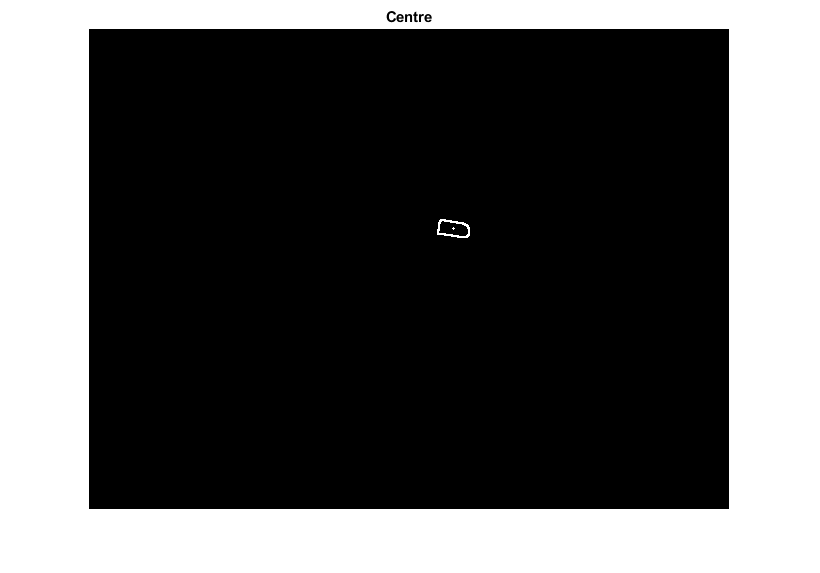

save('PObject_Lab.mat','PObject_Lab')

figure, imshow(Icentre)
title('Centre')